# Sensor Estimation for Spectral QE (Psych 221)

This tutorial introduces  **color** calculations that are relevant to camera  calibration. These calculations involve thinking about the sensor in the camera . As you perform the calculations, you should consider the relationship between how the camera encodes light, and then how the eye encodes light. 

Part of the tutorial will involve computations with surface reflectances and illuminants that are relevant to the Rendering tutorial.

- **Author**:    Wandell

- Date:  01.02.97

- Duration:  20 minutes

- Matlab 5:  Checked 01.06.98 BW

- Matlab 7:  Checked 01.04.08 BW 

ieInit  % Initialize ISETCam


## Surface Reflectance Functions

The Macbeth Color Checker is a set of 24 surfaces commonly used to evaluate color balancing systems.   The surfaces that make up the Color Checker were selected to match the reflectance functions of certain surfaces that are commonly used in television and film industry. Here is a picture of the MCC.

scene = sceneCreate;
sceneWindow(scene);

We  read in a matrix of surface reflectance data. The  columns of the macbethChart matrix represent the reflectances of the 24 surfaces.  

wavelength = 400:10:700;
macbethChart = ieReadSpectra('macbethChart',wavelength);

ieNewGraphWin; 
plotReflectance(wavelength,macbethChart);

### Reflectances of Individual Patches

ISETCam orders the patches starting from the upper left (1,1) and then counting down the rows to the white surface (4,1).  Thus, the white surface is the 4th column in the macbethChart matrix (macbethChart(:,4).  The entire series of neural patches is in columns 4, 8, 12, 16, 20, 24.  From the plot, notice that about 18% of the light at wavelength 500 nm is reflected by the "Green" surface. Here is the reflectance function of a red surface:

greenChip = 7; redChip = 11; whiteChip = 4; grayChip = 12;

ieNewGraphWin;
plot(wavelength,macbethChart(:,greenChip),'g-','LineWidth',2);hold on
plot(wavelength,macbethChart(:,redChip),'r--','LineWidth',2); hold on 
plot(wavelength,macbethChart(:,grayChip),'k:','LineWidth',2);
grid on; xlabel('Wavelength (nm)'); ylabel('Surface Reflectance');
title('Reflectance of Macbeth Surfaces'); 
legend('Green chip', 'Red chip','Gray chip');
hold off

## Calculating the Spectral Radiance from a Patch

This matrix tableau is a reference for how we calculate the device responses from the irradiance at the sensor.  In this example, we make the surface reflectance and illuminant explict. 

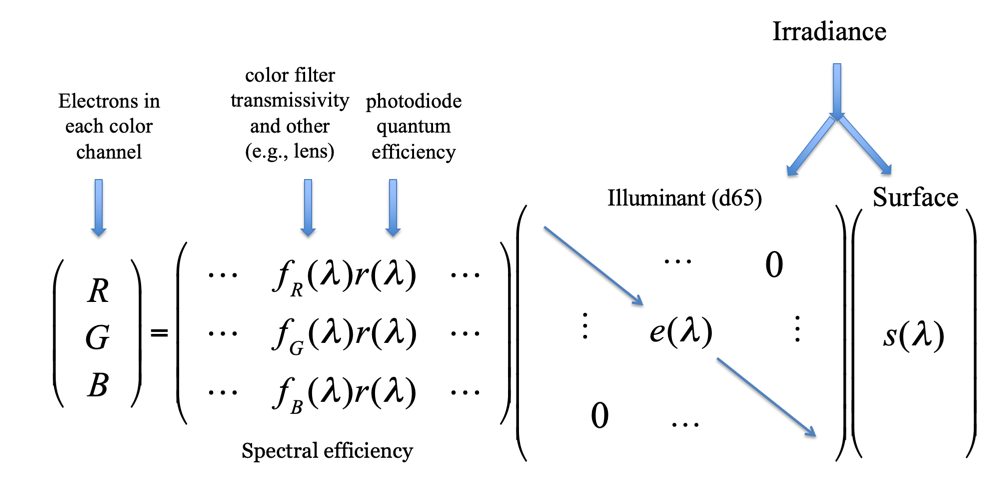

We have already loaded the surfaces.  Now, we load the illuminant.  The illuminant spectral power distribution (in energy units here) represents the amount of light from the light source at each wavelength. 

D65 = ieReadSpectra('D65.mat',wavelength);
ieNewGraphWin;
plot(wavelength,D65,'b','LineWidth',2); grid on
xlabel('Wavelength (nm)');
ylabel('Energy');
title('Spectral radiance energy of D65 illuminant (relative)');

### Multiply the Illuminant times the Surface Reflectances

The light scattered from the surface is the point-wise (wavelength by wavelength) product of the incident light and the reflectance of the surface at the each wavelength. There are lots of ways to do this calculation, but I find it simplest to perform it for all of the surfaces at once as a matrix product.  The matrix tableau shows how to do it for one surface.  If we stack up more columns in the surface matrix on the right, we will be doing it from multiple surfaces.

We change light vector into a diagonal matrix, and we multiply that matrix times a matrix whose columns contain the surface reflectance functions.

% These are approximations of the irradiances from the patches
spectral_signals = diag(D65)*macbethChart;

% As examples, plot the spectral signal scattered from the green and
% gray Macbeth surfaces.
ieNewGraphWin;
plot(wavelength,spectral_signals(:,greenChip),'g','LineWidth',2); hold on
plot(wavelength,spectral_signals(:,grayChip),'k','LineWidth',2);  hold off
xlabel('Wavelength (nm)'); ylabel('Reflected Energy');
title('Reflected energy of surfaces under D65')
legend('Green scatter','Gray scatter')
grid on

## Predicting how a Device Sensor Responds to the Light Sources

To calculate the expected response from a linear sensor given a radiance, we use the spectral-efficiency curves of the camera or other imaging device. The spectral responsivitiy of the three r,g,b sensors in a device I once calibrated are plotted here.

Notice that the three sensor spectral-efficiency curves hardly overlap.  This non-overlapping pattern is due to  the way this particular device was built:  It captured light using three using dichroic filters; this was one of the architectures I described in the novel color architectures.

sensors = ieReadSpectra('cMatch/camera', wavelength);

plot(wavelength(:), sensors,'LineWidth',2); grid on
xlabel('Wavelength (nm)'); ylabel('Responsivity')

### What the Device records is not the same as what the Retina Records

The device's sensors really don't look much like the cone spectral sensitivities in the human eye.  Here is an estimate of the cones!  This mis-match is something we need to correct for in digital image processing.  I call the methods that manage this 'sensor conversion':  We are converting the sensor data into a format that approximates what the human sensors would have measured.  

ncones = ieReadSpectra('SmithPokornyCones',wavelength);
ieNewGraphWin;
plot(wavelength(:),ncones,'LineWidth',2);
grid on
colororder({'r','g','b'}); % Color order override for newer matlab versions

## Sensor response to D65 Reflected from the Chart 

We can predict the (linear) sensor responses by a  matrix multiplication. The matrix product of the sensor sensitivites (in the rows) and the spectral signals (in the columns) generates the response  for each sensor class.

Notice the size of the rgb matrix.  It is $3 x 24$ because there are three types of sensors and 24 surfaces in the Macbeth Color Checker. 

rgbResponses = sensors'*spectral_signals;
size(rgbResponses)
colororder({'r','g','b'}); % Color order override for newer matlab versions

### The Gray-series RGB Values

We can plot the rgb responses of this scanner to the light scattered from the gray surfaces.  Before we create this plot, ask yourself what you think the values ought to be.In order of lightest to darkest, here are the rgb responses to the gray series patches.

graySeries = 4:4:24; 

ieNewGraphWin; hold on;
plot(graySeries,rgbResponses(1,graySeries)','ro', 'MarkerSize',12,'LineWidth',2); hold on;
plot(graySeries,rgbResponses(2,graySeries)','go', 'MarkerSize',12,'LineWidth',2); hold on;
plot(graySeries,rgbResponses(3,graySeries)','bo', 'MarkerSize',12,'LineWidth',2); 
grid on;
xlabel('Chip number'); ylabel('RGB values');


### The Gray-series Reflectances 

Let's compare the RGB values with the surface reflectance values.  They should match in relative amounts.  Take a moment to look at the 

ieNewGraphWin;
plot(wavelength,macbethChart(:,graySeries),'k-','LineWidth',2);
grid on;
xlabel('Wavelength (nm)'); ylabel('Reflectance');

## Estimate the Sensor's Spectral Efficiency

Suppose that we don't know the spectral properties of the scanner.  How could we estimate the wavelength tuning of the sensors in the scanner by making a set of measurements? We might be able to measure the scanner illuminant directly, just by opening the box during the scan.  So, figuring out the illuminant should be pretty easy.

Given the illuminant is known, how do we estimate the properties of the camera sensors?  We need to measure how the sensors respond to a calibrated target, like the Macbeth color-checker.  If we know the illuminant, then we can calculate the spectral signals arriving at the sensors.  We have a them already above as "spectral_signals." In general, we know that the rgbResponses are equal to 


$$RGB = (Camera Spectral Efficiency)*(Spectral Irradiance)$$


When we are calibrating, we know the irradiance and the rgbResponses. We want to estimate the scanner.  If you return to the matrix tableau to see what this equation represents, you will see that there are more unknowns than there are linear equations. Hence, it is impossible to estimate the scanner sensitivity uniquely from these measurements.  But, we can measure that part of the scanner sensitivity that falls within the column space of the spectral signals.  

One way to do this  isby calculating the "pseudo-inverse" of the matrix spectral_signals.

estimate = (rgbResponses*pinv(spectral_signals))';

ieNewGraphWin;
plot(wavelength,estimate(:,1),'r',  ...
     wavelength,estimate(:,2),'g', ...
     wavelength,estimate(:,3),'b', 'LineWidth',2)
grid on
xlabel('Wavelength'), ylabel('Responsivity')
title('Estimated sensor responses')

Notice that even for this computational example, the estimates are not perfect: there are noticeable differences between them and the original sensors.  But, the estimated sensors predict the responses perfectly.

rgbPred = estimate'*spectral_signals;
plot(rgbPred(:),rgbResponses(:),'o')
grid on

### Further Consideration of the Estimation Algorithms

Suppose we had fewer measurements samples.  How well would we have done on the estimation? 

l = 1:5:24;
estimate = (rgbResponses(:,l)*pinv(spectral_signals(:,l)))';

ieNewGraphWin;
plot(wavelength,estimate(:,1),'r', ...
     wavelength,estimate(:,2),'g', ...
     wavelength,estimate(:,3),'b','LineWidth',2)
grid on
xlabel('Wavelength'), ylabel('Responsivity')
title('Estimated sensor responses')

The new estimates are worse.  Notice, for example, that some of the values are negative - which is impossible! We might also ask how well the new estimates to in predicting the full set of responses, that is the responses to the surfaces not in the list, l.

rgbPred = estimate'*spectral_signals;
plot(rgbPred(:),rgbResponses(:),'o','MarkerSize',12)
xlabel('Predicted rgb'); ylabel('Measured rgb');
grid on

Try adding in some measurement noise to create a new estimate.  Then let's see how well we did.

rng('default');
n = 10*randn(size(rgbResponses));
sig = max(0,rgbResponses + n);
estimate = (sig(:,l)*pinv(spectral_signals(:,l)))';

### Future Discussion

The problem with these estimates is GENERALIZATION.  We do well on these data, but when new irradiances arise we are unlikely to predict the responses well.

In the future, you might think about cross-validation and other regularization constrains on the solution.